ecg1

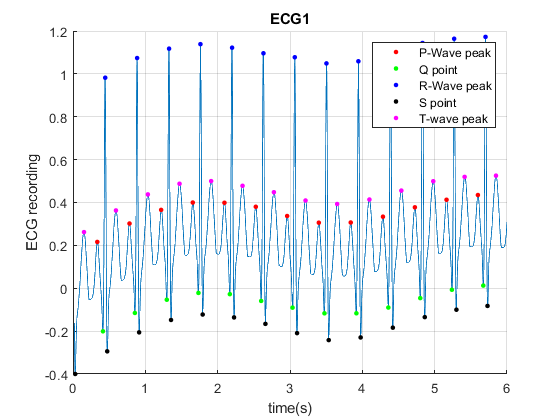

load('ecg1.mat'); %loads ecg1 file 
p1=[]; %creates vector with time for each consecutive P-Wave peak
q1=[]; %creates vector with time for each consecutive Q point
r1=[]; %creates vector with time for each consecutive R-Wave peak
s1=[]; %creates vector with time for each consecutive S point
t1=[]; %creates vector with time for each consecutive T-Wave peak
sum1=0;
hold on
grid on
plot (time(1:1532),ecg(1:1532)); %plots the ecg1 graph
title('ECG1')
ylabel('ECG recording');
xlabel('time(s)');
for i=1:length(time) %loop to check graph behaviour
    if marker(i)==1 %condition for P-Wave peak
        if i<=1532
           a1=plot(time(i),ecg(i),'.r','MarkerSize',10); %plots every P-Wave peak on graph
           p1(length(p1)+1)=time(i); %stores time for each P-Wave peak
        else
           p1(length(p1)+1)=time(i); %stores time for each P-Wave peak
        end
    end
    if marker(i)==2 %condition for Q point
        if i<=1532
           a2=plot(time(i),ecg(i),'.g','MarkerSize',10); %plots every Q point on graph
           q1(length(q1)+1)=time(i); %stores time for each Q Point 
        else
           q1(length(q1)+1)=time(i); %stores time for each Q Point
        end
    end
    if marker(i)==3 %condition for R-Wave peak
        if i<=1532
           a3=plot(time(i),ecg(i),'.b','MarkerSize',10); %plots every R-Wave peak on graph
           r1(length(r1)+1)=time(i); %stores time for each R-Wave peak   
        else
           r1(length(r1)+1)=time(i); %stores time for each R-Wave peak    
        end
    end
    if marker(i)==4 %condition for S point
        if i<=1532
           a4=plot(time(i),ecg(i),'.k','MarkerSize',10); %plots every S point on graph
           s1(length(s1)+1)=time(i); %stores time for each S Point 
        else
           s1(length(s1)+1)=time(i); %stores time for each S Point 
        end   
    end
    if marker(i)==5 %condition for T-Wave peak
        if i<=1532
           a5=plot(time(i),ecg(i),'.m','MarkerSize',10); %plots every T-Wave peak on graph
           t1(length(t1)+1)=time(i); %stores time for each T-Wave peak 
        else
           t1(length(t1)+1)=time(i); %stores time for each T-Wave peak  
        end
    end
end
legend([a1 a2 a3 a4 a5],{'P-Wave peak','Q point','R-Wave peak','S point', 'T-wave peak'});
hold off

pp1=60/(p1(2)-p1(1)); %calcultes the heart reate(P-P)
fprintf('Heart rate in the PP interval is %f.\n',pp1); %prints the heart rate

Heart rate in the PP interval is 134.736842.


rr1=60/(r1(2)-r1(1)); %calcultes the heart reate(R-R)
fprintf('Heart rate in the RR interval is %f.\n',rr1); %prints the heart rate

Heart rate in the RR interval is 135.929204.


for i=1:length(p1)
    sum1=sum1+(((p1(i)-t1(i))/2)+((q1(i)-p1(i))/2));
end
pr1=sum1/length(p1);
fprintf('Average PR interval is %f.\n',pr1); %prints the average interval

Average PR interval is 0.129966.


ecg2

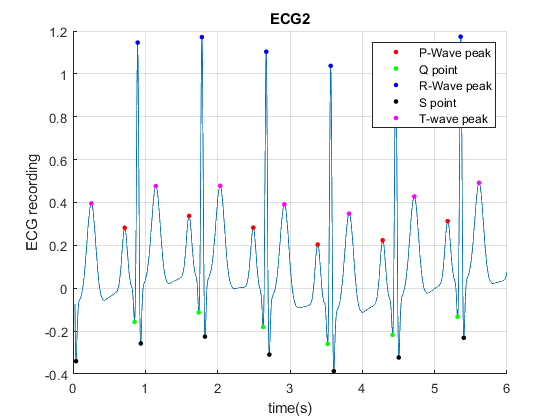

load('ecg2.mat'); %loads ecg2 file
p2=[]; %creates vector with time for each consecutive P-Wave peak
q2=[]; %creates vector with time for each consecutive Q point
r2=[]; %creates vector with time for each consecutive R-Wave peak
s2=[]; %creates vector with time for each consecutive S point
t2=[]; %creates vector with time for each consecutive T-Wave peak
sum2=0;
figure
hold on
grid on
plot (time(1:1530),ecg(1:1530)); %plots the ecg2 graph
title('ECG2')
ylabel('ECG recording');
xlabel('time(s)');
for k=1:length(time) %loop to check graph behaviour
    if marker(k)==1 %condition for P-Wave peak
        if k<=1530
           b1=plot(time(k),ecg(k),'.r','MarkerSize',10); %plots every P-Wave peak on graph
           p2(length(p2)+1)=time(k); %stores time for each P-Wave peak 
        else
           p2(length(p2)+1)=time(k); %stores time for each P-Wave peak 
        end       
    end
    if marker(k)==2 %condition for Q point
        if k<=1530
           b2=plot(time(k),ecg(k),'.g','MarkerSize',10); %plots every Q point on graph
           q2(length(q2)+1)=time(k); %stores time for each Q Point 
        else
           q2(length(q2)+1)=time(k); %stores time for each Q Point 
        end
    end
    if marker(k)==3 %condition for R-Wave peak
        if k<=1530
           b3=plot(time(k),ecg(k),'.b','MarkerSize',10); %plots every R-Wave peak on graph
           r2(length(r2)+1)=time(k); %stores time for each R-Wave peak 
        else
           r2(length(r2)+1)=time(k); %stores time for each R-Wave peak  
        end
    end
    if marker(k)==4 %condition for S point
        if k<=1530
           b4=plot(time(k),ecg(k),'.k','MarkerSize',10); %plots every S point on graph
           s2(length(s2)+1)=time(k); %stores time for each S Point 
        else
           s2(length(s2)+1)=time(k); %stores time for each S Point 
        end
    end
    if marker(k)==5 %condition for T-Wave peak
        if k<=1530
           b5=plot(time(k),ecg(k),'.m','MarkerSize',10); %plots every T-Wave peak on graph
           t2(length(t2)+1)=time(k); %stores time for each T-Wave peak 
        else
           t2(length(t2)+1)=time(k); %stores time for each T-Wave peak 
        end
    end
end
legend([b1 b2 b3 b4 b5],{'P-Wave peak','Q point','R-Wave peak','S point', 'T-wave peak'});
hold off

pp2=60/(p2(2)-p2(1)); %calcultes the heart reate(P-P)
fprintf('Heart rate in the PP interval is %f.\n',pp2); %prints the heart rate

Heart rate in the PP interval is 67.368421.


rr2=60/(r2(2)-r2(1)); %calcultes the heart reate(R-R)
fprintf('Heart rate in the RR interval is %f.\n',rr2); %prints the heart rate

Heart rate in the RR interval is 67.665198.


for i=1:length(p2)
    sum2=sum2+(((p2(i)-t2(i))/2)+((q2(i)-p2(i))/2));
end
pr2=sum2/length(p2);
fprintf('Average PR interval is %f.\n',pr2); %prints the average interval

Average PR interval is 0.299211.


ecg3

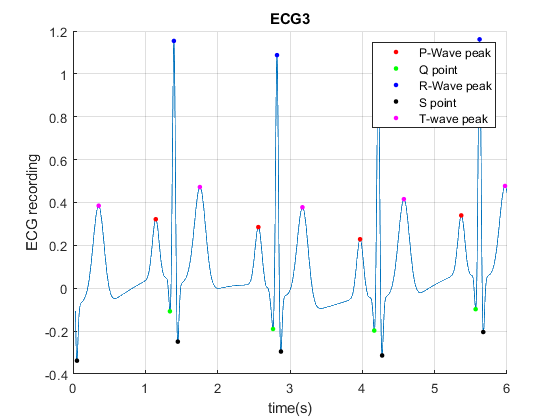

load('ecg3.mat'); %loads ecg3 file
p3=[]; %creates vector with time for each consecutive P-Wave peak
q3=[]; %creates vector with time for each consecutive Q point
r3=[]; %creates vector with time for each consecutive R-Wave peak
s3=[]; %creates vector with time for each consecutive S point
t3=[]; %creates vector with time for each consecutive T-Wave peak
sum3=0;
figure
hold on
grid on
plot (time(1:1528),ecg(1:1528)); %plots the ecg3 graph
title('ECG3')
ylabel('ECG recording');
xlabel('time(s)');
for h=1:length(time) %loop to check graph behaviour
    if marker(h)==1 %condition for P-Wave peak
        if h<=1528
           c1=plot(time(h),ecg(h),'.r','MarkerSize',10); %plots every P-Wave peak on graph
           p3(length(p3)+1)=time(h); %stores time for each P-Wave peak 
        else
           p3(length(p3)+1)=time(h); %stores time for each P-Wave peak  
        end
    end
    if marker(h)==2 %condition for Q point
        if h<=1528
           c2=plot(time(h),ecg(h),'.g','MarkerSize',10); %plots every Q point on graph
           q3(length(q3)+1)=time(h); %stores time for each Q Point 
        else
           q3(length(q3)+1)=time(h); %stores time for each Q Point 
        end
    end
    if marker(h)==3 %condition for R-Wave peak
        if h<=1528
           c3=plot(time(h),ecg(h),'.b','MarkerSize',10); %plots every R-Wave peak on graph
           r3(length(r3)+1)=time(h); %stores time for each R-Wave peak 
        else
           r3(length(r3)+1)=time(h); %stores time for each R-Wave peak 
        end
    end
    if marker(h)==4 %condition for S point
        if h<=1528
           c4=plot(time(h),ecg(h),'.k','MarkerSize',10); %plots every S point on graph
           s3(length(s3)+1)=time(h); %stores time for each S Point 
        else
           s3(length(s3)+1)=time(h); %stores time for each S Point 
        end
    end
    if marker(h)==5 %condition for T-Wave peak
        if h<=1528
           c5=plot(time(h),ecg(h),'.m','MarkerSize',10); %plots every T-Wave peak on graph
           t3(length(t3)+1)=time(h); %stores time for each T-Wave peak
        else
           t3(length(t3)+1)=time(h); %stores time for each T-Wave peak 
        end
    end
end
legend([c1 c2 c3 c4 c5],{'P-Wave peak','Q point','R-Wave peak','S point', 'T-wave peak'});
hold off

pp3=60/(p3(2)-p3(1)); %calcultes the heart reate(P-P)
fprintf('Heart rate in the PP interval is %f.\n',pp3); %prints the heart rate

Heart rate in the PP interval is 42.314050.


rr3=60/(r3(2)-r3(1)); %calcultes the heart reate(R-R)
fprintf('Heart rate in the RR interval is %f.\n',rr3); %prints the heart rate

Heart rate in the RR interval is 42.082192.


for i=1:length(p3)
    sum3=sum3+(((p3(i)-t3(i))/2)+((q3(i)-p3(i))/2));
end
pr3=sum3/length(p3);
fprintf('Average PR interval is %f.\n',pr3); %prints the average interval

Average PR interval is 0.493801.
